# Laplace Transform Lab: Solving ODEs using Laplace Transform in MATLAB

This lab will teach you to solve ODEs using a built in MATLAB Laplace transform function `laplace`.

There are five (5) exercises in this lab that are to be handed in. Write your solutions in a separate file, including appropriate descriptions in each step.

Include your name and student number in the submitted file.

## Student Information

## Exercise 1

f(t) = exp(2*t)*t^3;
% a)
laplace(f) % F(s) = 6/(s-2)^4
F(s) = (s - 1)*(s - 2)/(s*(s + 2)*(s - 3));
% b)
ilaplace(F) % f(t) = (6*exp(-2*t))/5 + (2*exp(3*t))/15 - 1/3
clear all;
syms f(t) a s t;
F(s) = laplace(f(t)); % outputs laplace(f(t), t, s)
% c)
laplace(exp(a*t)*f(t), t, s) % outputs laplace(f(t), t, s - a) = F(s-a)

$$ans = \mathrm{laplace}\left(f\left(t\right),t,s-a\right)$$


% MATLAB knows to take the Laplace transform of f(t), then shift the input
% right by a units (the third output argument is s-a, meaning that whatever
% function we get F(s), the variable we use instead is s-a => F(s-a) is the
% final answer.

## Exercise 2

clear all;
syms a s f(t) t;
a = 5;
G(s) = laplace(heaviside(t-a)*f(t-a), t, s) % exp(-5*s)*laplace(f(t), t, s) = exp(-as)*F(s)

$$G(s) = {\mathrm{e}}^{-5\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

F(s) = laplace(f(t), t, s) % laplace(f(t), t, s) = F(s)

$$F(s) = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

G(s)/F(s) % exp(-5*s)

$$ans = {\mathrm{e}}^{-5\,s}$$


% as MATLAB has shown, G(s)/F(s) = exp(-5*s). Rearranging, we get G(s) =
% exp(-5*s)*F(s). Here we chose a = 5, but this works for all a with G(s) =
% exp(-a*s)*F(s). To achieve this result, evaluations for F(s) and G(s)
% were made for any generic f(t), where F and G where formulated according
% to the question definitions. Dividing the two function of s resulted in a
% final function independent of f(t), G, and F -> exp(-5*s). The expression
% was rearranged to arrive at the final equation.

## Exercise 3

clear all;
syms t y(t) Y s;

ODE = diff(y(t), t, 3) + 2*diff(y(t), t, 2) + diff(y(t), 1) + 2*y(t) == -cos(t);

% convert ODE to an algebraic equation using Laplace transform
L_ODE = laplace(ODE);

% initial values:
L_ODE = subs(L_ODE, y(0), 0);
L_ODE = subs(L_ODE,subs(diff(y(t), t), t, 0),0);
L_ODE = subs(L_ODE, subs(diff(y(t), t, 2), t, 0), 0);

% solve for Y(s):
L_ODE = subs(L_ODE, laplace(y(t), t, s), Y);
Y = solve(L_ODE, Y);

% solution to the original ODE:
y(t) = ilaplace(Y)

$$y(t) = \frac{2\,{\mathrm{e}}^{-2\,t}}{25}-\frac{2\,\cos\left(t\right)}{25}+\frac{3\,\sin\left(t\right)}{50}+\frac{t\,\cos\left(t\right)}{10}-\frac{t\,\sin\left(t\right)}{5}$$


% check this indeed equals -cos(t), or the right hand side of the ODE:
LHS = diff(y(t), t, 3) + 2*diff(y(t), t, 2) + diff(y(t), t) + 2*y(t)

$$LHS = -\cos\left(t\right)$$


% the particular solution also satisifies the ODE:
g(t) = (t*cos(t))/10 - (t*sin(t))/5;
LHS = diff(g(t), t, 3) + 2*diff(g(t), t, 2) + diff(g(t), t) + 2*g(t)

$$LHS = -\cos\left(t\right)$$

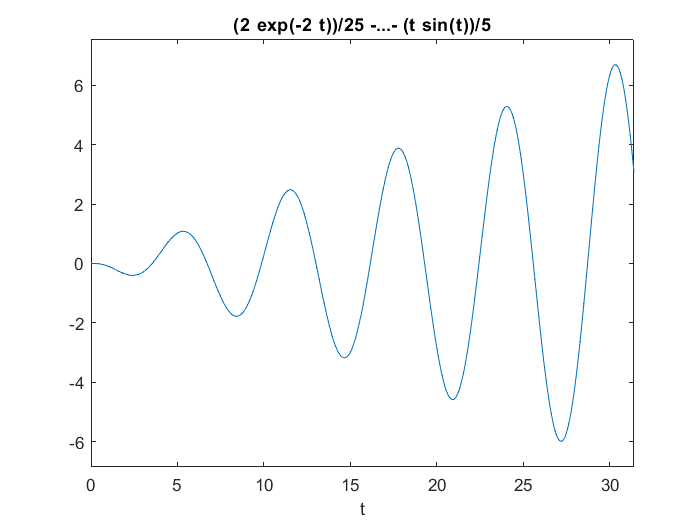

ezplot(y, [0,10*pi]);


% there is no initial condition for which y remains bounded as t approaches
% infinity. To see this, obtain a general solution for this ODE by first
% solving for the complimentary solution: r^3+2r^2+r+2 = 0 => r = -i, i, -2
% So y_c = Acos(t) + Bsin(t) + Cexp(-2t). The particular solution can be
% found using MATLAB, it's the last two terms of y(t) from above: y_p =
% tsin(t)/5 + tcos(t)/10. Therefore, the general solution for the system is
% y(t) = Acos(t) + Bsin(t) + Cexp(-2t) + tsin(t)/5 + tcos(t)/10. Since none
% of the A, B, C terms have an isolated t, we cannot "cancel out" the
% particular solution. So any initial condition will eventually grow to
% infinity.

## Exercise 4

% g(t) = 3u_{02} + u_{25}(t+1) + 5u_{5}, where u_{ab} = u_a - u_b
% g(t) = 3u_0 + (t-2)u_2 + (4-t)u_5

% declare variables, functions:
syms t y(t) Y s; % CAN'T PUT COMMAS HERE

% expressing g(t) in terms of shifted Heaviside functions:
g(t) = 3*heaviside(t) + (t-2)*heaviside(t-2) + (4-t)*heaviside(t-5);

% expressing the ODE:
ODE = diff(y(t), t, 2) + 2*diff(y(t), t, 1) + 5*y(t) == g(t);

% taking the Laplace transform:
L_ODE = laplace(ODE);

% Initial conditions: y(0) = 2, y'(0) = 1
L_ODE = subs(L_ODE, y(0), 2);
L_ODE = subs(L_ODE,subs(diff(y(t), t), t, 0),1);

% set Y = laplace(f(t)), solve for Y:
L_ODE = subs(L_ODE, laplace(y(t), t, s), Y);
Y = solve(L_ODE, Y);

% take the inverse Laplace of Y(s) to get y(t):
y(t) = ilaplace(Y)

$$y(t) = \begin{array}{l} \mathrm{heaviside}\left(t-2\right)\,\left(\frac{t}{5}+\frac{2\,{\mathrm{e}}^{2-t}\,\left(\cos\left(2\,t-4\right)-\frac{3\,\sin\left(2\,t-4\right)}{4}\right)}{25}-\frac{12}{25}\right)-\mathrm{heaviside}\left(t-5\right)\,\left(\frac{t}{5}+\frac{2\,{\mathrm{e}}^{5-t}\,\left(\sigma_{3}-\frac{3\,\sigma_{2}}{4}\right)}{25}-\frac{27}{25}\right)+2\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)-\sigma_{1}\right)-\frac{3\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\sigma_{1}\right)}{5}+\frac{5\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-t}}{2}+\mathrm{heaviside}\left(t-5\right)\,\left(\frac{{\mathrm{e}}^{5-t}\,\left(\sigma_{3}+\frac{\sigma_{2}}{2}\right)}{5}-\frac{1}{5}\right)+\frac{3}{5}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(2\,t\right)}{2}\\ \sigma_{2}=\sin\left(2\,t-10\right)\\ \sigma_{3}=\cos\left(2\,t-10\right) \end{array}$$

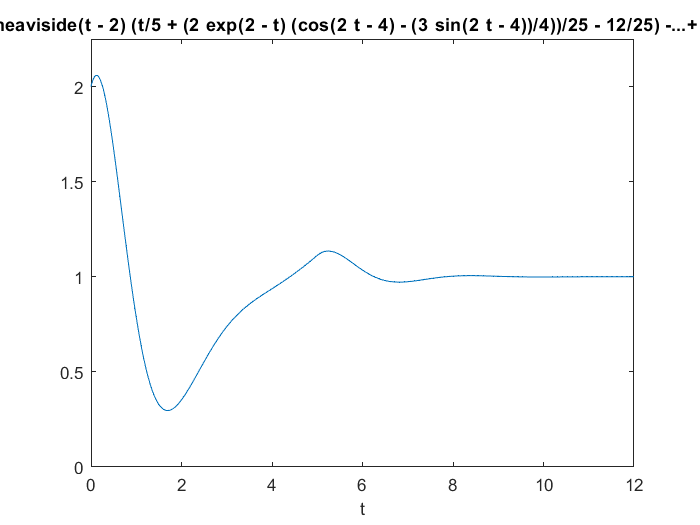


% plot for |t| in |[0,12]| and |y| in |[0,2.25]|:
ezplot(y, [0,12, 0,2.25]);


% In general here are the steps to solve a non-homogenous ODE with a
% piecewise differentiable forcing function g(t):
% - expression the forcing function in terms of Heaviside unit step
% functions
% - Convert the differential equation to an algebraic equation using
% laplace(f(t)), and set initial conditions using the subs function
% - solve the algebraic equation in terms of Y(s)
% - use the ilaplace function to convert Y(s) => y(t), the solution to the
% original ODE

## Exercise 5

syms t tau y(tau) s
I=int(exp(-2*(t-tau))*y(tau),tau,0,t)

$$I = \int_{0}^{t}{\mathrm{e}}^{2\,\tau -2\,t}\,y\left(\tau \right)\mathrm{d}\tau$$

laplace(I,t,s) % output: laplace(y(t), t, s)/(s+2)

$$ans = \frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{s+2}$$


% the given integral expression is equivalent to (exp(2t) * y(t))(t), where
% (f*g) denotes the convolution between the functions f and g. We know that
% laplace((f*g)(t)) = F(s)G(s). We know that the laplace transform of
% exp(2t) is 1/(s+2). Therefore, the laplace transform of the convolution
% is the product between 1/(s+2) and laplace(y(t)), as correctly displayed by
% MATLAB.